% Author: Sai Pushpak Nandanoori
% ----------------------------------------------
% Code description:
%{
This code is written as part of MACSER project funded by ASCR Office. 
This code generates data for a network of nonlinear oscillators without control, 
computes different variants of DMD, compares their learning rates and
eigenvalues. 

Date created: June 23, 2022 
Date last updated: Apr 01, 2026
%}
% ----------------------------------------------
clear; close all; clc; tic
set(0,'DefaultAxesFontSize',12)

% Add the functions to the MATLAB path 
addpath('functions/')
% Specify the path to save the plots 
plot_save_path = sprintf('%s/Figures',pwd);

SavePlots = 0; % 1 - save plots; 0 - don't save 

## Network generation 

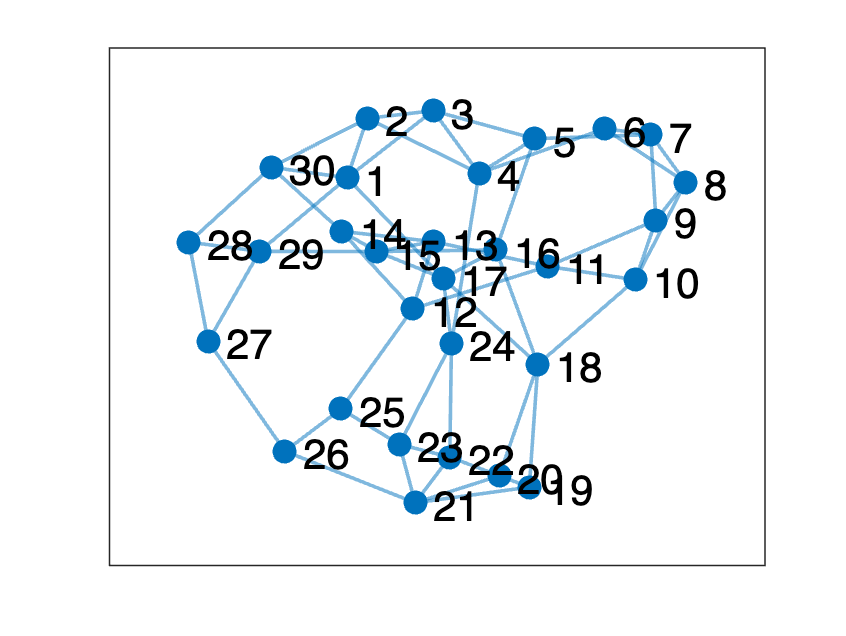

% Define parameters for the network of nonlinear oscillators
rng(115123,'v5normal')

N = 30;                     % Number of oscillators:
n = 2;                      % number of states per oscillator (agent)
Adj = SmallWorld(N,0.2,2);  % Adjoint matrix of a small world network
G = graph(Adj);             % Graph of adjoint matrix 
D = diag(sum(Adj,2));       % Degree matrix
Lp = D - Adj;               % Laplacian matrix

figure
h1 = plot(G, 'MarkerSize',7,'LineWidth',1.2);
h1.NodeFontSize = 14;

if SavePlots 
    savefig(gcf, sprintf('%s/VDP_Oscillators_network', plot_save_path))
    saveas(gcf, sprintf('%s/VDP_Oscillators_network', plot_save_path),'png')
end

% Computing network density 
total_possible_edges = N*(N-1)*0.5; % Nc2
total_edges = size(G.Edges,1); 
network_density = total_edges/total_possible_edges;
fprintf('Network density = %.3f\n', network_density)

Network density = 0.138


Van der Pol network of oscillators

% System Parameters
Mu    = 0.15*rand(N,1); % 0.67+0.15*rand(N,1);
Omega = diag(0.8*rand(N,1));

Vdp_sys = @(t,x)[x(N+1:2*N); diag(Mu.*(1-x(1:N).^2))*x(N+1:2*N) - Omega*Lp*x(1:N)];

## ODE Simulation and collect time-series data: 

% Running time-domain simulations with num_ics number of initial conditions
% and collecting the previous and forwarded data as needed.
num_ics = 1;
Xp_data = [];
Xf_data = [];
X_dot = [];
simT = 100;
simDT = 2e-2;
num_of_data_points = simT/simDT; 
x0 = 1.4*randn(n*N,num_ics);

for k = 1:num_ics
    [t,x_data] = ode45(Vdp_sys,0:simDT:simT,x0(:,k));
    Xp_data = [Xp_data x_data(1:end-1,:)'];
    Xf_data = [Xf_data x_data(2:end,:)'];
end

fprintf('Size of Xp_data: %dx%d \n',size(Xp_data))

Size of Xp_data: 60x5000 


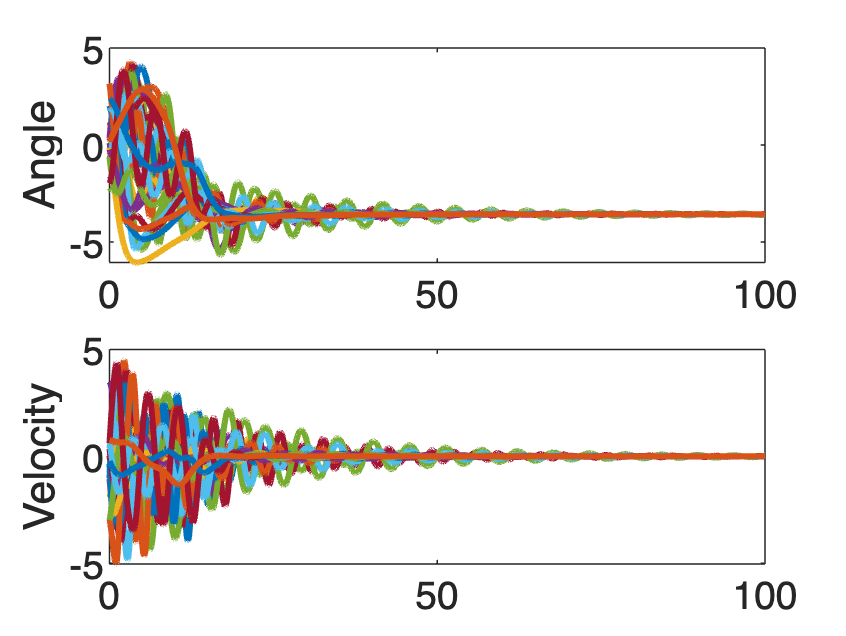


figure
subplot(2,1,1)
plot(t,x_data(:,1:N),'LineWidth',2)
ylabel('Angle')
subplot(2,1,2)
plot(t,x_data(:,N+1:2*N),'LineWidth',2)
ylabel('Velocity')


if SavePlots 
    savefig(gcf, sprintf('%s/VDP_Oscillators_states', plot_save_path))
    saveas(gcf, sprintf('%s/VDP_Oscillators_states', plot_save_path),'png')
end

Data processing: Rearranging the data by grouping the states for every node. 

% Stack the time-series data such that the states belonging to an agent are
% clubbed together. Assuming two states at each agent
as1 = 1:N;
as2 = N+1:2*N;
as3 = [as1' as2']';
as  = as3(:);

Xp = Xp_data(as,:);
Xf = Xf_data(as,:);

## (Robust) DMD computation:

LAMBDA = 0.012; % 0.012 Regularization weight
tic
K_DMD = DMD(Xp, Xf, LAMBDA); 
loss_DMD = K_DMD*Xp - Xf;

disp('******* DMD *******')

******* DMD *******


fprintf('Computation time: %.3f seconds\n',toc)

Computation time: 0.017 seconds


fprintf('Koopman Loss: \t \t %0.4f\n',norm(loss_DMD,"fro"))

Koopman Loss: 	 	 0.2099


fprintf('Largest eigen value:\t %.4f\n',max(abs(eig(K_DMD))))

Largest eigen value:	 1.0000


## D-DMD Computation: 

[Tpp, Tfp, Rpp] = compute_transformation_matrices(Adj, N, n); 

tic
K_D_DMD = D_DMD(Xp,Xf,LAMBDA, N, Tfp); 
loss_D_DMD = K_D_DMD*Xp - Xf;

disp('******* D-DMD *******')

******* D-DMD *******


fprintf('Computation time: %.3f seconds\n',toc)

Computation time: 0.010 seconds


fprintf('Koopman Loss: \t \t %0.4f\n',norm(loss_D_DMD,"fro"))

Koopman Loss: 	 	 0.2099


fprintf('Largest eigen value:\t %.4f\n',max(abs(eig(K_D_DMD))))

Largest eigen value:	 1.0000


## SD-DMD Computation: 

tic
K_S_D_DMD = SD_DMD(Xp,Xf,LAMBDA, N, Tpp, Tfp, Rpp);
loss_SD_DMD = K_S_D_DMD*Xp - Xf;

disp('******* SD-DMD *******')

******* SD-DMD *******


fprintf('Computation time: %.3f seconds\n',toc)

Computation time: 0.005 seconds


fprintf('Koopman Loss: \t \t %0.4f\n',norm(loss_SD_DMD,"fro"))

Koopman Loss: 	 	 0.7835


fprintf('Largest eigen value:\t %.4f\n',max(abs(eig(K_S_D_DMD))))

Largest eigen value:	 1.0055


## R-DMD Computation:

(not considering the windowed R-DMD as of now)

T1 = 1; T2 = num_of_data_points - 1; 
tic
K_R_DMD = R_DMD(Xp,Xf,LAMBDA, N, T1, T2);
loss_R_DMD = K_R_DMD{end}*Xp - Xf;

disp('******* R-DMD *******')

******* R-DMD *******


fprintf('Computation time: %.3f seconds\n',toc)

Computation time: 17.987 seconds


loss_R_DMD_full = zeros(n*N,length(K_R_DMD));
for k1 = 1:length(K_R_DMD)
    loss_R_DMD_full(:,k1) = K_R_DMD{k1}*Xp(:,k1) - Xf(:,k1); 
end 
fprintf('Koopman Loss: \t \t %0.4f\n',norm(loss_R_DMD,"fro"))

Koopman Loss: 	 	 0.2760


fprintf('Largest eigen value:\t %.4f\n',max(abs(eig(K_R_DMD{end}))))

Largest eigen value:	 1.0000


## RD-DMD Computation:

(Recursive distributed DMD)

tic
K_RD_DMD = RD_DMD(Xp,Xf,LAMBDA, N, Tfp, T1, T2); 
loss_RD_DMD = K_RD_DMD{end}*Xp - Xf;

disp('******* RD-DMD *******')

******* RD-DMD *******


fprintf('Computation time: %.3f seconds\n',toc)

Computation time: 31.377 seconds


loss_RD_DMD_full = zeros(n*N,length(K_RD_DMD));
for k1 = 1:length(K_RD_DMD)
    loss_RD_DMD_full(:,k1) = K_RD_DMD{k1}*Xp(:,k1) - Xf(:,k1); 
end 
fprintf('Koopman Loss: \t \t %0.4f\n',norm(loss_RD_DMD,"fro"))

Koopman Loss: 	 	 0.2854


fprintf('Largest eigen value:\t %.4f\n',max(abs(eig(K_RD_DMD{end}))))

Largest eigen value:	 1.0000


## RSD-DMD Computation:

(Recursive sparse distributed DMD)

tic
K_RSD_DMD = RSD_DMD(Xp,Xf,LAMBDA, N, Tpp, Tfp, Rpp, T1, T2); 
loss_RSD_DMD = K_RSD_DMD{end}*Xp - Xf;

disp('******* RSD-DMD *******')

******* RSD-DMD *******


fprintf('Computation time: %.3f seconds\n',toc)

Computation time: 3.162 seconds


loss_RSD_DMD_full = zeros(n*N,length(K_RSD_DMD));
for k1 = 1:length(K_RSD_DMD)
    loss_RSD_DMD_full(:,k1) = K_RSD_DMD{k1}*Xp(:,k1) - Xf(:,k1); 
end 
fprintf('Koopman Loss: \t \t %0.4f\n',norm(loss_RSD_DMD,"fro"))

Koopman Loss: 	 	 0.7078


fprintf('Largest eigen value:\t %.4f\n',max(abs(eig(K_RSD_DMD{end}))))

Largest eigen value:	 1.0000


### Eigenvalues plot

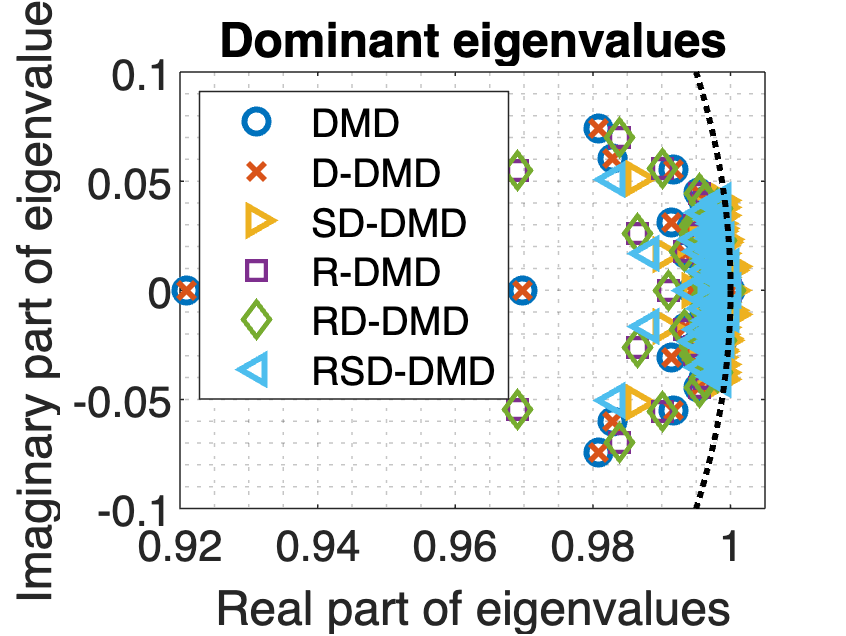

figure
p1 = plot(real(eig(K_DMD)), imag(eig(K_DMD)), 'o','color','#0072BD','LineWidth',2,'MarkerSize',8); hold on
p2 = plot(real(eig(K_D_DMD)), imag(eig(K_D_DMD)), 'x','color','#D95319','LineWidth',2,'MarkerSize',8);
p3 = plot(real(eig(K_S_D_DMD)), imag(eig(K_S_D_DMD)), '>','color','#EDB120','LineWidth',2,'MarkerSize',8);
p4 = plot(real(eig(K_R_DMD{end})), imag(eig(K_R_DMD{end})), 's','color','#7E2F8E','LineWidth',2,'MarkerSize',8);
p5 = plot(real(eig(K_RD_DMD{end})), imag(eig(K_RD_DMD{end})), 'diamond','color','#77AC30','LineWidth',2,'MarkerSize',8);
p6 = plot(real(eig(K_RSD_DMD{end})), imag(eig(K_RSD_DMD{end})), '<','color','#4DBEEE','LineWidth',2,'MarkerSize',8);
legend([p1(1), p2(1), p3(1), p4(1), p5(1), p6(1)],'DMD','D-DMD','SD-DMD', 'R-DMD', 'RD-DMD','RSD-DMD','location','northwest','Interpreter','None');
theta = linspace(0,2*pi,2000);
p = plot(cos(theta),sin(theta),'k:','LineWidth',2,'HandleVisibility','off');
xlim([0.92, 1.005])
ylim([-0.1, 0.1])
grid minor
title('Dominant eigenvalues')
xlabel('Real part of eigenvalues')
ylabel('Imaginary part of eigenvalues')

if SavePlots 
    savefig(gcf, sprintf('%s/VDP_Oscillators_eigenvalues', plot_save_path))
    saveas(gcf, sprintf('%s/VDP_Oscillators_eigenvalues', plot_save_path),'png')
end

### Loss plot

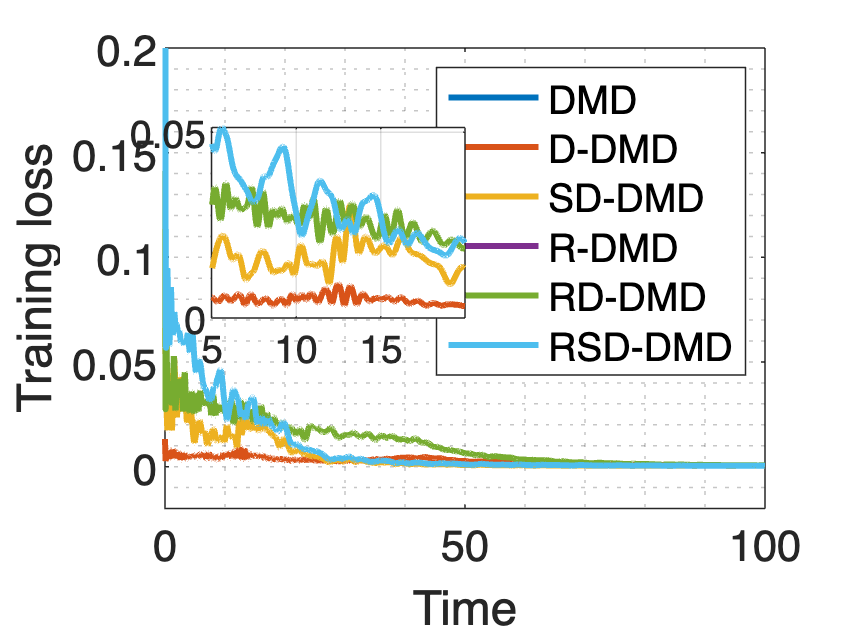

vecnorm_loss_DMD = vecnorm(loss_DMD);
vecnorm_loss_D_DMD = vecnorm(loss_D_DMD);
vecnorm_loss_SD_DMD = vecnorm(loss_SD_DMD(:,3:end));
vecnorm_loss_R_DMD_full= vecnorm(loss_R_DMD_full(:,3:end));
vecnorm_loss_RD_DMD_full = vecnorm(loss_RD_DMD_full(:,3:end));
vecnorm_loss_RSD_DMD_full = vecnorm(loss_RSD_DMD_full(:,3:end));

figure
p1 = plot(t(1:end-1),vecnorm_loss_DMD,'color','#0072BD','LineWidth',2); hold on; 
p2 = plot(t(1:end-1),vecnorm_loss_D_DMD,'color','#D95319','LineWidth',2); 
p3 = plot(t(3:end-1),vecnorm_loss_SD_DMD,'color','#EDB120','LineWidth',2); 
p4 = plot(t(3:end-1),vecnorm_loss_R_DMD_full,'color','#7E2F8E','LineWidth',2); 
p5 = plot(t(3:end-1),vecnorm_loss_RD_DMD_full,'color','#77AC30','LineWidth',2);
p6 = plot(t(3:end-1),vecnorm_loss_RSD_DMD_full,'color','#4DBEEE','LineWidth',2);
ylim([-0.02, 0.2])
legend([p1(1), p2(1), p3(1), p4(1), p5(1), p6(1)],'DMD','D-DMD','SD-DMD', 'R-DMD', 'RD-DMD','RSD-DMD','location','northeast','Interpreter','None');
xlabel('Time')
ylabel('Training loss') 
grid minor

inset = axes('Position', [0.25, 0.5, 0.3, 0.3]);
box on;

% Plot in inset
x1 = 250;
x2 = 252;
y1 = 1000;
x_inset = t(x1:y1);
x2_inset = t(x2:y1);

p1 = plot(x_inset,vecnorm_loss_DMD(x1:y1),'color','#0072BD','LineWidth',2); hold on; 
p2 = plot(x_inset,vecnorm_loss_D_DMD(x1:y1),'color','#D95319','LineWidth',2); 
p3 = plot(x2_inset,vecnorm_loss_SD_DMD(x2:y1),'color','#EDB120','LineWidth',2); 
p4 = plot(x2_inset,vecnorm_loss_R_DMD_full(x2:y1),'color','#7E2F8E','LineWidth',2); 
p5 = plot(x2_inset,vecnorm_loss_RD_DMD_full(x2:y1),'color','#77AC30','LineWidth',2);
p6 = plot(x2_inset,vecnorm_loss_RSD_DMD_full(x2:y1),'color','#4DBEEE','LineWidth',2);
grid on;


if SavePlots 
    savefig(gcf, sprintf('%s/VDP_Oscillators_training_loss', plot_save_path))
    saveas(gcf, sprintf('%s/VDP_Oscillators_training_loss', plot_save_path),'png')
end
